# Data preparation: cleaning

The data in "biopsies_raw.csv" has not been cleaned:

clear all;
data = readtable('biopsies_raw.csv');

Clean the data and split it ready for training and testing a classifier.

Marks are available for:

- Appropriately addressing: duplicated examples; irrelevant features; missing values [5 marks]

- Identifying and removing the extreme outlier for the "smoothness_mean" feature [3 marks]

- Splitting the data up into an appropriately named training dataset and testing dataset [8 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:

%get overview d data
summary(data)


Variables:

    id: 570×1 double

        Values:

            Min             8670
            Median    9.0616e+05
            Max       9.1132e+08

    diagnosis: 570×1 cell array of character vectors

    radius_mean: 570×1 double

        Values:

            Min               6.981    
            Median            13.34    
            Max               28.11    
            NumMissing        1        

    texture_mean: 570×1 double

        Values:

            Min             9.71    
            Median        18.835    
            Max            39.28    

    perimeter_mean: 570×1 double

        Values:

            Min            43.79      
            Median         86.21      
            Max            188.5      

    area_mean: 570×1 double

        Values:

            Min          143.5   
            Median      548.75   
            Max           2501   

    


help unique

 unique Set unique.
    C = unique(A) for the array A returns the same values as in A but with 
    no repetitions. C will be sorted.    
   
    C = unique(A,'rows') for the matrix A returns the unique rows of A.
    The rows of the matrix C will be in sorted order.
   
    [C,IA,IC] = unique(A) also returns index vectors IA and IC such that
    C = A(IA) and A = C(IC) (or A(:) = C(IC), if A is a matrix or array).  
   
    [C,IA,IC] = unique(A,'rows') also returns index vectors IA and IC such
    that C = A(IA,:) and A = C(IC,:). 
   
    [C,IA,IC] = unique(A,OCCURRENCE) and
    [C,IA,IC] = unique(A,'rows',OCCURRENCE) specify which index is returned
    in IA in the case of repeated values (or rows) in A. The default value
    is OCCURRENCE = 'first', which returns the index of the first occurrence 
    of each repeated value (or row) in A, while OCCURRENCE = 'last' 


%delete duplicate values
 uniqueRows= unique(data,'rows')

uniqueRows = 569×32 table
     id       diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavi

summary(uniqueRows)


Variables:

    id: 569×1 double

        Values:

            Min             8670
            Median    9.0602e+05
            Max       9.1132e+08

    diagnosis: 569×1 cell array of character vectors

    radius_mean: 569×1 double

        Values:

            Min              6.981     
            Median           13.355    
            Max              28.11     
            NumMissing       1         

    texture_mean: 569×1 double

        Values:

            Min            9.71     
            Median        18.84     
            Max           39.28     

    perimeter_mean: 569×1 double

        Values:

            Min            43.79      
            Median         86.24      
            Max            188.5      

    area_mean: 569×1 double

        Values:

            Min          143.5   
            Median       551.1   
            Max           2501   

    


%delete irrelevant features
uniqueRows(:, 'id') = []

uniqueRows = 569×31 table
     diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    

summary(uniqueRows)


Variables:

    diagnosis: 569×1 cell array of character vectors

    radius_mean: 569×1 double

        Values:

            Min              6.981     
            Median           13.355    
            Max              28.11     
            NumMissing       1         

    texture_mean: 569×1 double

        Values:

            Min            9.71     
            Median        18.84     
            Max           39.28     

    perimeter_mean: 569×1 double

        Values:

            Min            43.79      
            Median         86.24      
            Max            188.5      

    area_mean: 569×1 double

        Values:

            Min          143.5   
            Median       551.1   
            Max           2501   

    smoothness_mean: 569×1 double

        Values:

            Min            0.05263     
            Median         0.09592     
           


%missing value features - find indices for the missing 
% values by passing the data in the relevant column of the 
% table to isnan()..
uniqueRows(isnan(uniqueRows{: , 'radius_mean'}), :) = []

uniqueRows = 568×31 table
     diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    

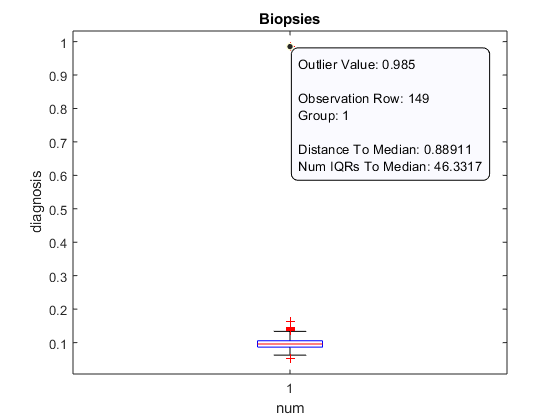




%Identifying and removing the extreme outlier for the 
% "smoothness_mean" feature
boxplot(uniqueRows{:, 'smoothness_mean'})
xlabel('num')
ylabel('diagnosis')
title('Biopsies');


% %delete outlier
% uniqueRows(149, :) = []
% boxplot(uniqueRows{:, 'smoothness_mean'})
% 
% % Seperate dta up into training and testing dataset using 
% %horizontal split to avoid overfitting data
% nTest = round(0.20 * size(data,1))
% 
% %shuffle data with randperm
% rng(1)
% 
% % shuffle the data and create a testing dataset and a training dataset:
% data_shuffled = data(randperm(size(data,1)), :);
% data_test = data_shuffled(1:1:nTest, :);
% size(data_test)
% data_train = data_shuffled(nTest+1:1:end, :);
% size(data_train)


